# Magined Movement EGG For BCI Applications

Most demonstrations of algorithms on BCI data are evaluating classification of EEG trials, i.e., windowed EEG signals for fixed length, where each trial corresponds to a specific mental state. But in BCI applications with asynchronous feedback one is faced with the problem that the classifier has to be applied continuously to the incoming EEG without having cues of when the subject is switching her/his intention. This data set poses the challenge of applying a classifier to continuous EEG for which no cue information is given.

Another issue that is addressed in this data set is that the evaluation data contains periods in which the user has no control intention. During those intervals the classifier is supposed to return 0 (no affiliation to one of the target classes).

## **Technical Information**

The recording was made using BrainAmp MR plus amplifiers and a Ag/AgCl electrode cap. Signals from 59 EEG positions were measured that were most densely distributed over sensorimotor areas. Signals were band-pass filtered between 0.05 and 200 Hz and then digitized at 1000 Hz with 16 bit (0.1 uV) accuracy. We provide also a version of the data that is downsampled at 100 Hz (first low-pass filtering the original data (Chebyshev Type II filter of order 10 with stopband ripple 50dB down and stopband edge frequency 49Hz) and then calculating the mean of blocks of 10 samples).

## **Format of the Data**

Given are continuous signals of 59 EEG channels and, for the calibration data, markers that indicate the time points of cue presentation and the corresponding target classes.

Data are provided in **Matlab** format (`*.mat`) containing variables:

- `cnt`: the continuous EEG signals, size [time x channels]. The array is stored in datatype `INT16`. To convert it to uV values, use `cnt= 0.1*double(cnt);` in Matlab.

- `mrk`: structure of target cue information with fields (the file of evaluation data does *not* contain this variable)

- `pos`: vector of positions of the cue in the EEG signals given in unit *sample*, length #cues

- `y`: vector of target classes (-1 for class one or 1 for class two), length #cues

- `nfo`: structure providing additional information with fields

- `fs`: sampling rate,

- `clab`: cell array of channel labels,

- `classes`: cell array of the names of the motor imagery classes,

- `xpos`: x-position of electrodes in a 2d-projection,

- `ypos`: y-position of electrodes in a 2d-projection.

As alternative, data is also provided in zipped **ASC II** format:

- `*_cnt.txt`: the continuous EEG signals, where each row holds the values for all channels at a specific time point

- `*_mrk.txt`: target cue information, each row represents one cue where the first value defines the time point (given in unit *sample*), and the second value the target class (-1 for class one or 1 for class two). For evaluation data *no* `*_mrk.txt` file is provided.

- `*_nfo.txt`: contains other information as described for the matlab format.

## **Block Diagram**

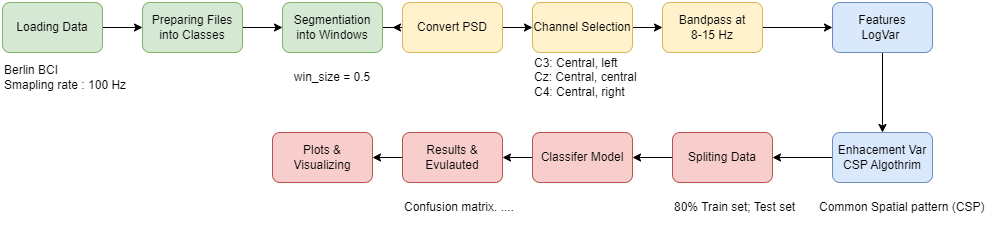

data = load('data/BCICIV_calib_ds1d.mat');

sample_rate = data.nfo.fs

sample_rate = 100

eeg_signal = data.cnt';
[nchannels, nsamples] = size(eeg_signal)

nchannels = 59

nsamples = 190473



channel_names = data.nfo.clab;

events_onsets = data.mrk.pos;
events_code =  data.mrk.y;

labels = zeros(1, nsamples);
labels(1, events_onsets) = events_code;

nclasses = length(data.nfo.classes);
class_1 = data.nfo.classes(1);
class_2 = data.nfo.classes(2);

Now, let me print informations of data

fprintf('Shape of EEG: %d \n', size(eeg_signal))

Shape of EEG: 59 
Shape of EEG: 190473 


fprintf('Sample rate: %d \n', sample_rate)

Sample rate: 100 


fprintf('Number of channels: %d', nchannels)

Number of channels: 59


disp(['Channel names: %s' channel_names])

  Columns 1 through 12

    'Channel names: %s'    'AF3'    'AF4'    'F5'    'F3'    'F1'    'Fz'    'F2'    'F4'    'F6'    'FC5'    'FC3'

  Columns 13 through 24

    'FC1'    'FCz'    'FC2'    'FC4'    'FC6'    'CFC7'    'CFC5'    'CFC3'    'CFC1'    'CFC2'    'CFC4'    'CFC6'

  Columns 25 through 37

    'CFC8'    'T7'    'C5'    'C3'    'C1'    'Cz'    'C2'    'C4'    'C6'    'T8'    'CCP7'    'CCP5'    'CCP3'

  Columns 38 through 49

    'CCP1'    'CCP2'    'CCP4'    'CCP6'    'CCP8'    'CP5'    'CP3'    'CP1'    'CPz'    'CP2'    'CP4'    'CP6'

  Columns 50 through 60

    'P5'    'P3'    'P1'    'Pz'    'P2'    'P4'    'P6'    'PO1'    'PO2'    'O1'    'O2'



fprintf('Number of events: %d', length(events_onsets))

Number of events: 200

disp(['Event codes:' unique(events_code)])

Event codes: 


disp(['Class labels:' data.nfo.classes])

    'Class labels:'    'left'    'right'



fprintf('Number of classes: %d', nclasses)

Number of classes: 2

## **Segmention & Visualiztion**

**Segmention**

Segmentation involves dividing continuous EEG data into smaller segments or epochs. Each segment corresponds to a specific event or activity.

% Window size recommanded 0.5 - 2.5 second which mean 2 second
window_size = 2 * sample_rate;
% trials = number of channels * windows samples * number of remark classes
trials = zeros(59, window_size, 200);

for sample = 1:length(events_onsets)
    window_start =  events_onsets(sample);
    trials(:, :, sample) = eeg_signal(:, window_start:(window_start + window_size - 1));
end

size(trials)

ans =     59   200   200



% 1 class of left; -1 class of right; 
onsets_left = trials(:, :, find(events_code == 1));
onsets_right = trials(:, :, find(events_code == -1));

size(onsets_left)

ans =     59   200   100


size(onsets_right)

ans =     59   200   100


**Visualiztion**

**Left Movement Signal**

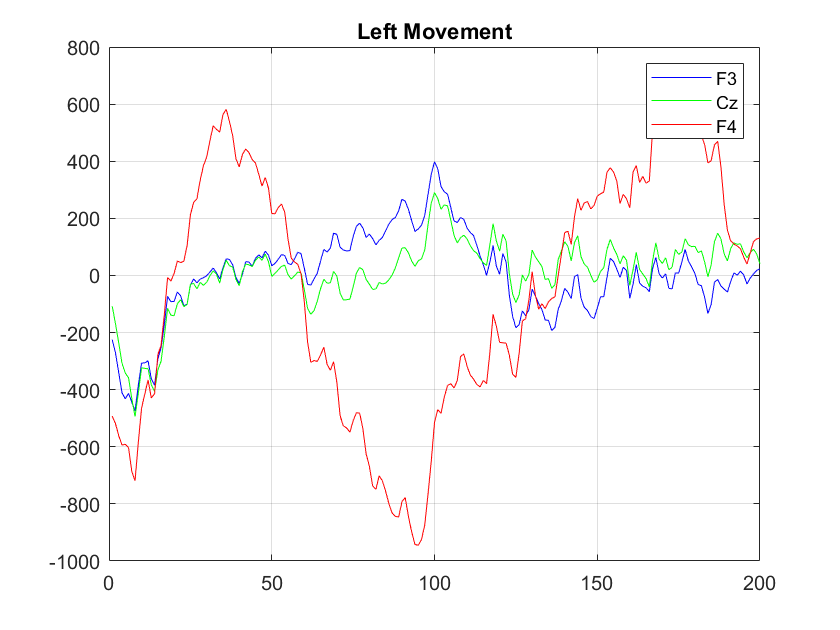

% Left Movement Signal
F3_left = onsets_left(4, :, 1);
Cz_left = onsets_left(6, :, 1);
F4_left = onsets_left(8, :, 1);

figure(1); title('Left Movement');

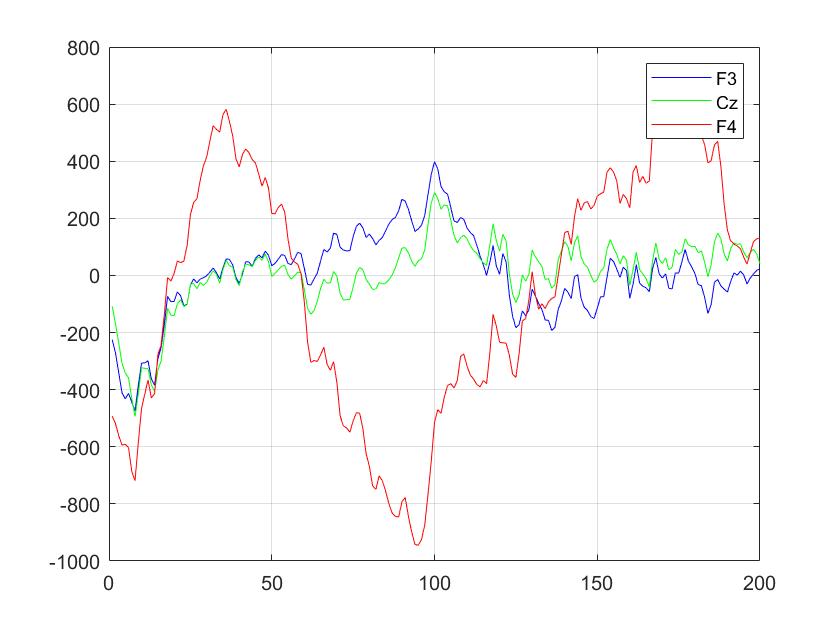

plot(F3_left, '-b'); hold on;
plot(Cz_left, '-g'); hold on;
plot(F4_left, '-r'); hold off; legend('F3','Cz','F4'); grid on;

**Right Movement Signal**

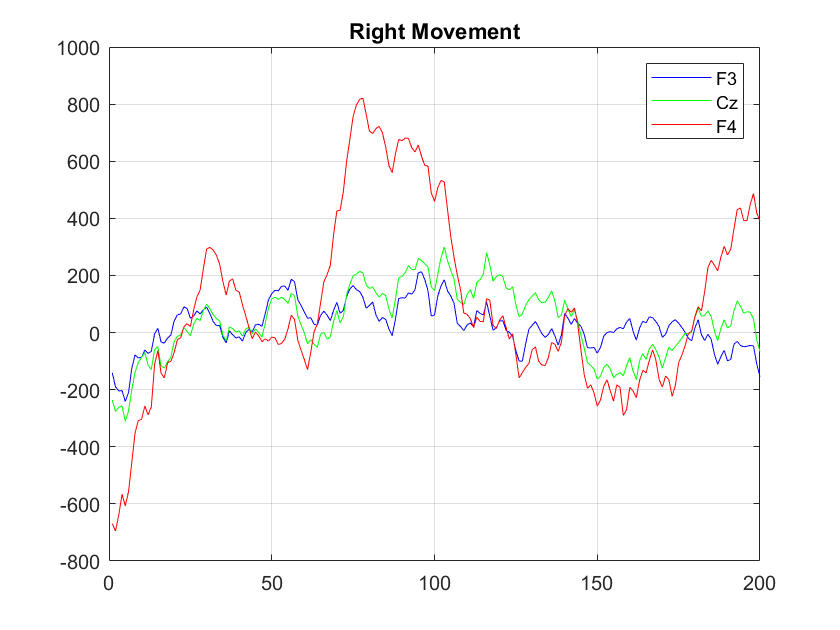

% Right Movement Signal
F3_right = onsets_right(4, :, 1);
Cz_right = onsets_right(6, :, 1);
F4_right = onsets_right(8, :, 1);

figure(2); title('Right Movement');

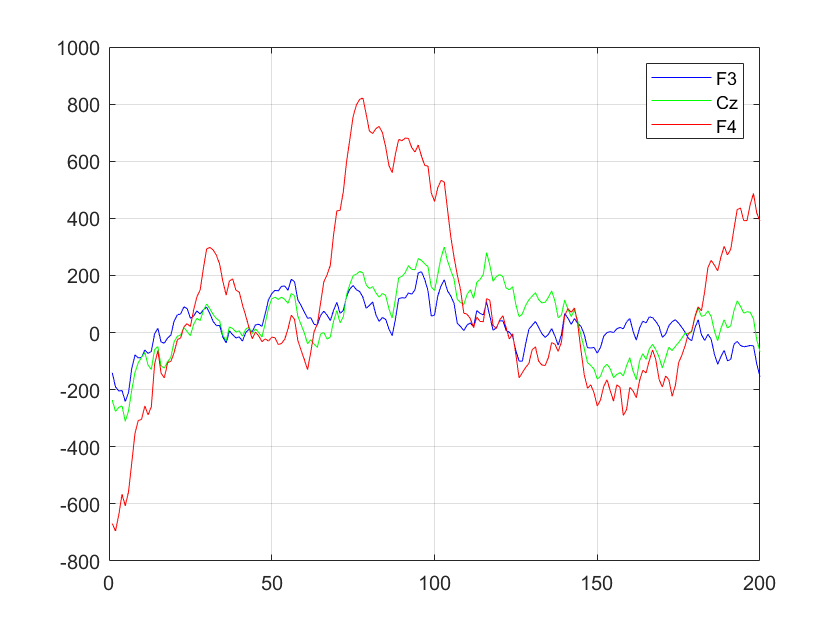

plot(F3_right, '-b'); hold on;
plot(Cz_right, '-g'); hold on;
plot(F4_right, '-r'); hold off; legend('F3','Cz','F4'); grid on;

### **Feature Engineering **

**Feature engineering** for **EEG signals** involves extracting relevant information from the raw EEG data to enhance its usefulness in various applications.

**F3 Channel PSD**

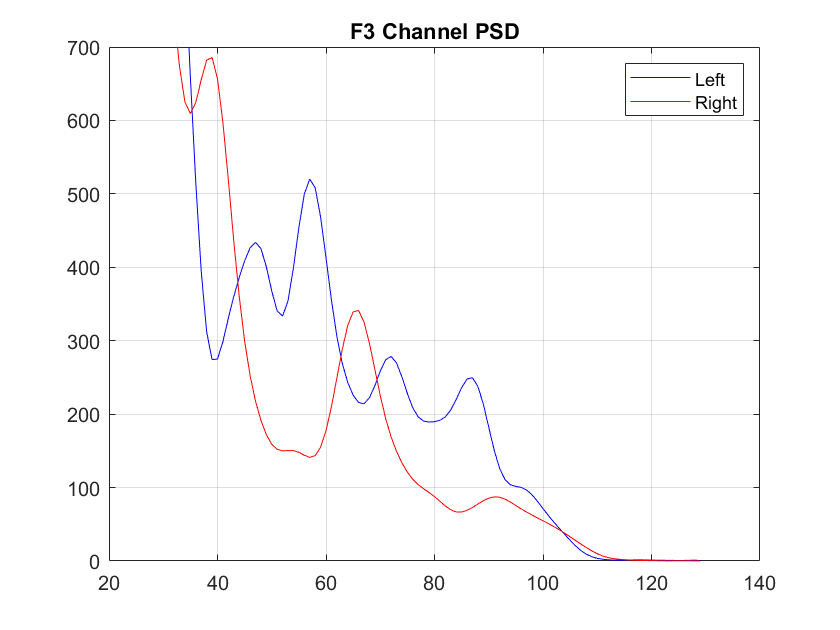

f3xx_left = pwelch(double(F3_left));
f4xx_left = pwelch(double(F4_left));

f3xx_right = pwelch(double(F3_right));
f4xx_right = pwelch(double(F4_right));

figure(3); title('F3 Channel PSD');

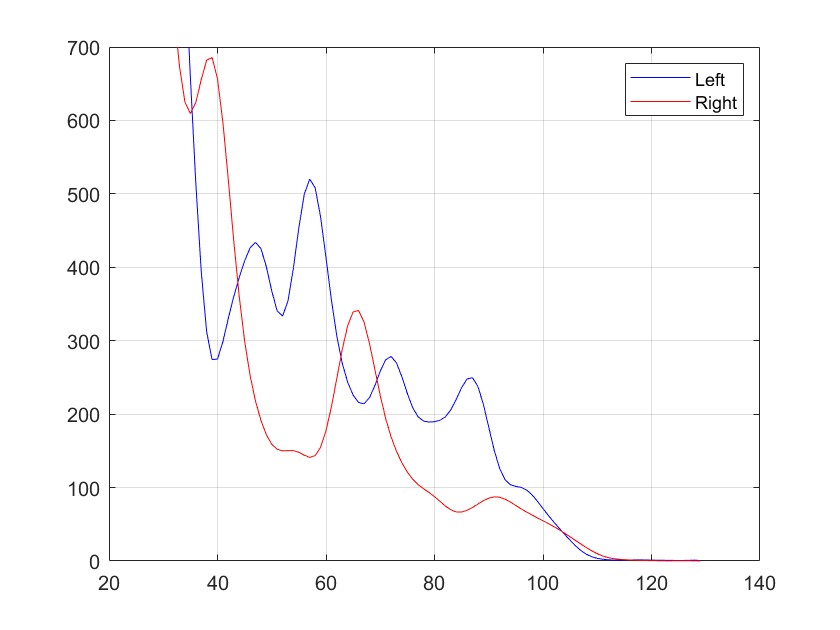

plot(f3xx_left, '-b'); hold on; 
plot(f3xx_right, '-r'); hold off; ylim([0 700]);
legend('Left', 'Right'); grid on;

**F4 Channel PSD**

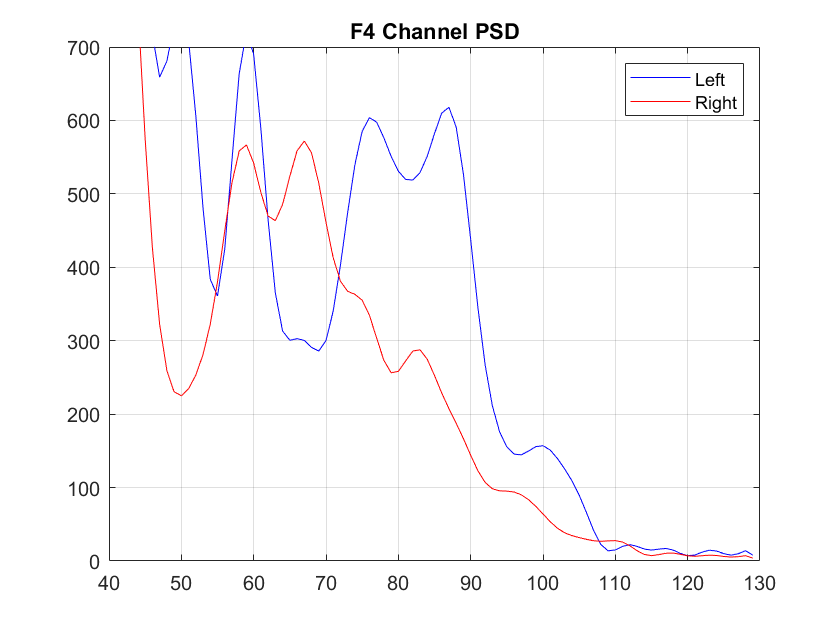


figure(4); title('F4 Channel PSD');

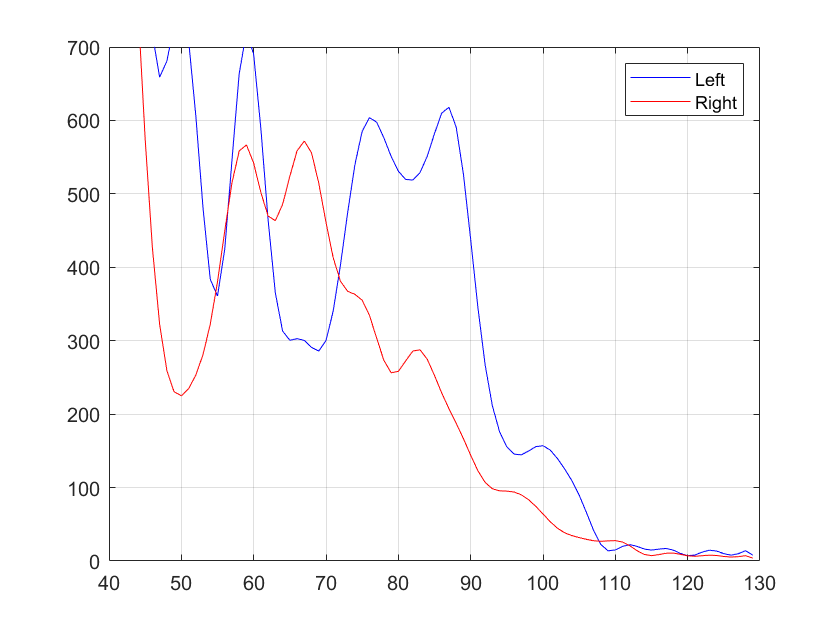

plot(f4xx_left, '-b'); hold on; 
plot(f4xx_right, '-r'); hold off; ylim([0 700]);
legend('Left', 'Right'); grid on;